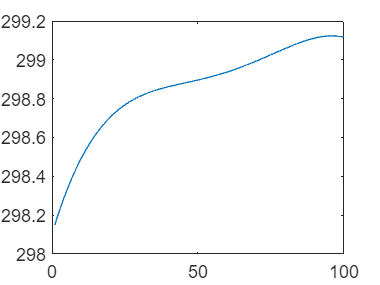

 %initialize parameter
    clc,clear
    t=linspace(0,0.1,100);
    y=L_Tight(t);
    plot(y)

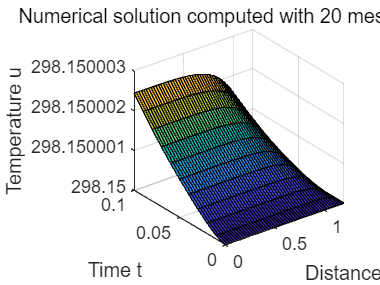

    k_fiber=1;
    d=0.6;                      %单根纤维的直径  mm 
    h=2*d;                      %织物的厚度  mm
    rho_s=0.6;                  %经密6/1cm
    rho_w=0.8;                  %维密8/1cm
    a=1/rho_s;                  %经向长度mm
    b=1/rho_w;                  %纬向长度mm
    T_end=0.1;             
    m = 0;
    x = linspace(0,h,50);       %单位 mm
    t = 0:0.01:T_end;   %单位s
    sol = pdepe(m,@(x,t,u,dudt)pdex1pde(x,t,u,dudt,k_fiber),@pdex1ic,@pdex1bc,x,t);
    u = sol(:,:,1);
    % index=int64([0,0.0198,0.0397,0.0595,0.0793,0.0992]*10000+1);  
    % T=u(index,1);
    % T_e=[25;25.5751;25.6930;25.8069;25.8960;25.9709]+273.15;
    % f=sum((T-T_e).^2);
    surf(x,t,u)
    title('Numerical solution computed with 20 mesh points.')
    xlabel('Distance x')
    ylabel('Time t')
    zlabel('Temperature u')
    hold off

function [c,f,s] = pdex1pde(x,t,u,dudx,k_fiber)
    alpha_tol=0.663;                        % 总扩散率 mm^2/s 对此变化相对较敏感
    cp=0.5;                                 %单位  Mj/m^3·K
    k_tol=0.033;                            %热导率 W/(m·K)
    rho_tol=k_tol/(cp*alpha_tol);           %总密度  W/(m·K)   mm^2/s   
    k_air=0.0296;                           %单位 W/(m·K)
    theta_s=19.8/360*2*pi;                  %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi;                 %纬纱弯曲角度 rad
   % alpha=S1*alpha_air+S2*air*air_f;        %截面热导率
    c=1/alpha_tol; 
    f = dudx;
    h=50*1e-6;
    s=h*(L_Tight(t)-u);
end

function u0 = pdex1ic(x)
    u0 = 298.15;
end
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t)   
    k_tol=0.033;              %总热导率 W/(m·K)
    A=1.2/k_tol/0.9709;
    pl = 0;   
    ql =1;
    pr = ur - 298.15;
    qr = 0;
end
function u=L_Tight(t)
  p=[-59599.9047557005	14375.0113350970	-1218.80638780507	47.3729535516151	298.152007531907];
  u = p(1).*t.^4 + p(2).*t.^3 + p(3).*t.^2 + p(4).*t + p(5);
end
